# **pNormalised Cut and Image Segmentation**

**Mathematics for Computing - 4**

Team C - 12

- Subash B (CB.SC.U4AIE24254)

- Sai Kushal Boggarapu (CB.SC.U4AIE24252)

- Naveen K (CB.SC.U4AIE24235)

- Cibikumar B (CB.SC.UA4IE24212)

## Introduction

Image segmentation is the process of dividing an image into multiple regions or objects that share common features such as brightness, color, or texture. Traditional segmentation methods like thresholding, region growing, or clustering often fail in complex images where objects have **gradual intensity changes, overlapping regions, or textured backgrounds**.

To address these challenges, **Shi and Malik (2000)** proposed the **Normalized Cut (Ncut) method**, a graph-based spectral image segmentation technique. The main idea is to represent the image as a **graph**, where pixels are nodes and similarity between pixels forms the edges. Unlike simple cuts, which often favor **small isolated regions**, Ncut introduces a **normalization term** to balance the partition sizes and produce meaningful segmentation.

In essence: **group pixels that are similar and separate pixels that are dissimilar**, while keeping partitions balanced.

# 1. Load Image and Pre-processing

Image segmentation begins with loading the input image and preparing it for processing.

The image is converted to **double precision** so that mathematical operations such as similarity computation and spectral decomposition can be performed accurately.

We also extract the **image height and width**, which will be used later for mapping segmentation results back to the image.

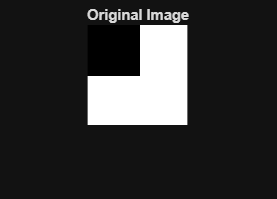

clear; clc; close all;

I = im2double(imread('img8.png'));

[h,w,~] = size(I);

figure
imshow(I)
title('Original Image')

# 2. Superpixel Over-Segmentation

Instead of treating every pixel as a graph node (which would create thousands of nodes), we first perform **superpixel segmentation**.

Superpixels group nearby pixels with similar colors into small regions.

Advantages:

- Reduces computational cost

- Preserves image boundaries

- Makes graph construction more stable

In this step we use MATLAB's **SLIC superpixel algorithm**.

Each superpixel will later become a node in the graph.

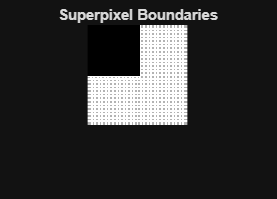

numSuperpixels = 800;

[L,N] = superpixels(I,numSuperpixels);

figure
imshow(boundarymask(L).*I + I*0.7)
title('Superpixel Boundaries')

Where

- **L** → label matrix assigning each pixel to a superpixel

- **N** → number of superpixels detected

# 3. Superpixel Feature Extraction

Each superpixel must be represented by a **feature vector**.

We compute:

- **Mean color (R,G,B)** inside the superpixel

- **Normalized spatial position (x,y)** of the superpixel centroid

Thus each superpixel node has a **5-dimensional feature vector**: $f_i=[R_i,G_i,B_i,x_i,y_i]$

These features allow the algorithm to measure similarity between superpixels.

stats = regionprops(L,'PixelIdxList','Centroid');

features = zeros(N,5);

Rch = I(:,:,1);
Gch = I(:,:,2);
Bch = I(:,:,3);

for i = 1:N

    idx = stats(i).PixelIdxList;

    R = mean(Rch(idx));
    G = mean(Gch(idx));
    B = mean(Bch(idx));

    cx = stats(i).Centroid(1)/w;
    cy = stats(i).Centroid(2)/h;

    features(i,:) = [R G B cx cy];

end

# 4. Edge Map for Boundary Awareness

Edges in the image represent strong boundaries between objects.

To prevent segmentation from crossing these boundaries, we compute the **image gradient magnitude**.

Higher gradient → stronger edge → lower similarity between regions.

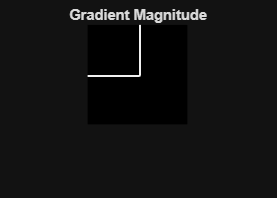

gray = rgb2gray(I);

G = imgradient(gray);

sigma_g = std(G(:));

figure
imshow(G,[])
title('Gradient Magnitude')

Where

- **G** = gradient magnitude image

- $\sigma_g$ = gradient normalization factor

# 5. Self-Tuning Similarity Matrix

We now construct a **similarity graph**.

Each superpixel becomes a **node**.

Edge weights measure similarity between nodes using:

- **Feature distance**

- **Edge strength**

**Self-Tuning Spectral Clustering**

Instead of using a fixed Gaussian scale parameter, we use **self-tuning sigma values** computed from nearest neighbors.

This makes the algorithm adapt to local data density.

Distance between nodes:

    
$$D_{ij}=||f_i - f_j||$$


Similarity weight:

    
$$W_{ij}=edgeFactor \cdot e^{-D_{ij}^2/(\sigma_i \sigma_j)}$$


k_nn = 7;

D = zeros(N,N);

for i = 1:N
    for j = 1:N
        dif = features(i,:) - features(j,:);
        d = 0;
        for k = 1:5
            d = d + dif(k)^2;
        end
        D(i,j) = sqrt(d);

    end
end

[sorted,~] = sort(D,2);

sigma = sorted(:,k_nn);

W = zeros(N,N);

for i = 1:N
    for j = 1:N

        edgeFactor = exp(-(G(round(stats(i).Centroid(2)), ...
                        round(stats(i).Centroid(1)))^2) / sigma_g^2);

        W(i,j) = edgeFactor * exp(-(D(i,j)^2)/(sigma(i)*sigma(j)+eps));

    end
end

W = (W + W')/2;

The matrix **W** is the **weighted adjacency matrix of the graph**.

# 6. Graph Laplacian Construction

Normalized Cut segmentation is based on the **graph Laplacian**.

First compute the **degree matrix**

$D_{ii}=\sum_jW_{ij}$�

Then compute the **Laplacian**


$$L = D - W$$


The Laplacian encodes connectivity structure of the graph.

d = sum(W,2);

Dmat = diag(d);

Lmat = Dmat - W;

# 7. Spectral Decomposition

The normalized cut problem is solved using **spectral graph theory**.

We compute the smallest eigenvectors of:


$$Lx = \lambda D x$$


The eigenvectors reveal natural partitions in the graph.

kmax = 10;

[eigVecs,eigVals] = eigs(Lmat,Dmat,kmax,'smallestabs');

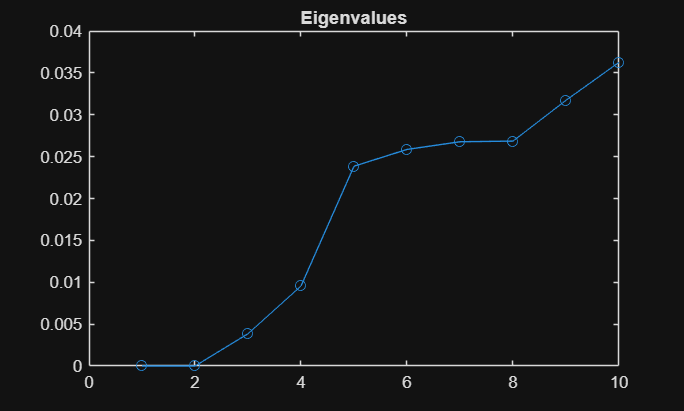


eigVals = diag(eigVals);

figure
plot(eigVals,'o-')
title('Eigenvalues')

# 8. Automatic Segment Detection (Eigen Gap)

The **Eigen Gap heuristic** estimates the number of segments.

The optimal number of clusters corresponds to the largest gap between consecutive eigenvalues.


$$k = argmax(\lambda_{i+1} - \lambda_i)$$


gaps = diff(eigVals);

[~,k] = max(gaps(2:end));

k = k + 1;
k = 2;

disp(['Estimated segments: ',num2str(k)])

Estimated segments: 2


# 9. Spectral Embedding

Each node is represented by the first **k eigenvectors**.

This maps nodes into a **k-dimensional spectral space**.

Rows are normalized to improve clustering stability.

Y = eigVecs(:,1:k);

Y = bsxfun(@rdivide,Y,sqrt(sum(Y.^2,2))+eps);

# 10. Clustering in Spectral Space

The final segmentation is obtained by clustering points in spectral space.

We use **k-means clustering**.

Each cluster corresponds to one **image segment**.

labels = kmeans(Y,k,'Replicates',20);

# 11. Map Superpixels Back to Image

Each superpixel label is mapped back to its pixels.

This converts the clustering result into a **pixel-level segmentation image**.

seg = zeros(h,w);

for i = 1:N
    seg(stats(i).PixelIdxList) = labels(i);
end

# 12. Visualizing Segmentation

Finally we visualize the segmentation.

Two displays are shown:

- Colored segmentation map

- Segmentation overlay on original image

figure
imshow(I)
title('Original Image')

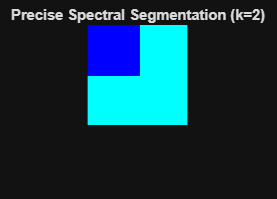


figure
imshow(label2rgb(seg,'jet','k','shuffle'))
title(['Precise Spectral Segmentation (k=',num2str(k),')'])

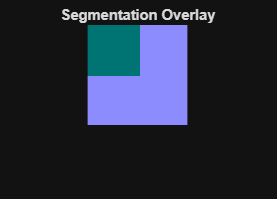


figure
imshow(I)
hold on

overlay = label2rgb(seg);

hImg = imshow(overlay);

set(hImg,'AlphaData',0.45)

title('Segmentation Overlay')

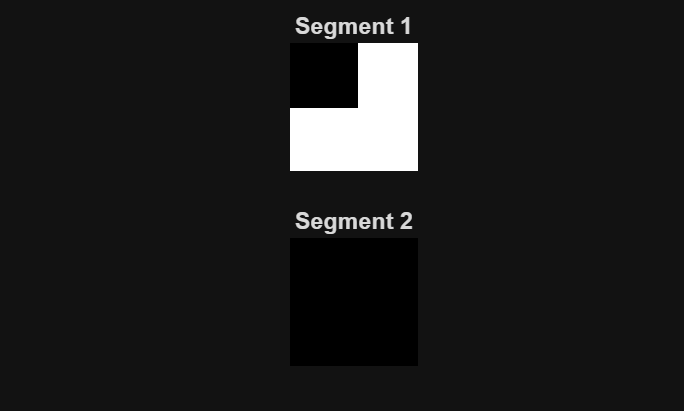



figure
rows = ceil(sqrt(k));
cols = ceil(k/rows);

for i = 1:k
    mask = (seg == i);
    mask3 = repmat(mask,[1 1 3]);
    
    segmentImage = I .* mask3;
    
    subplot(rows, cols, i)
    imshow(segmentImage)
    title(['Segment ', num2str(i)], 'FontSize', 14)
end